clear all;

load idealECG.mat;
fs = 128;
N = length(idealECG);
t = (0:N-1)/fs;

% SNR = 10;
n_50 = 0.2 * sin(2 * pi * 50 * t);
% nECG = awgn(idealECG,SNR,'measured')+n_50;
% 
% save("nECG.mat","nECG");
load nECG.mat;

std(nECG-idealECG)

ans = 0.1646

std(nECG-idealECG-n_50)

ans = 0.0851

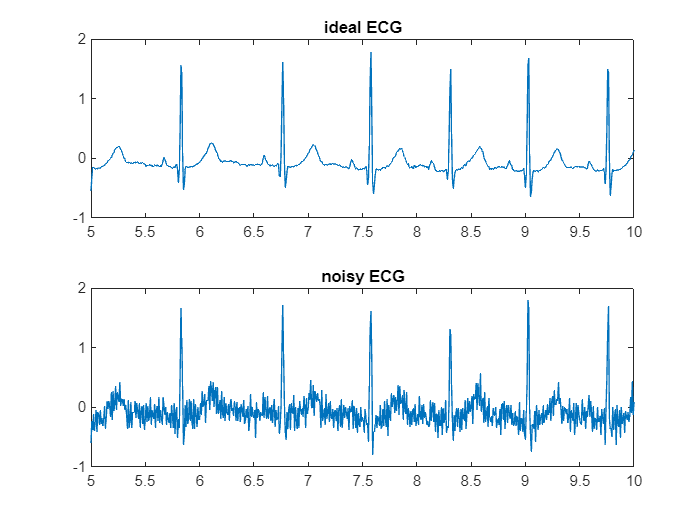

figure(1);
subplot(2,1,1);
plot(t,idealECG);
xlim([5,10]);
title('ideal ECG');

subplot(2,1,2);
plot(t,nECG);
xlim([5,10]);
title("noisy ECG");
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Original_and_Noisy_ECG.png');

## Scaler Kalman filter 

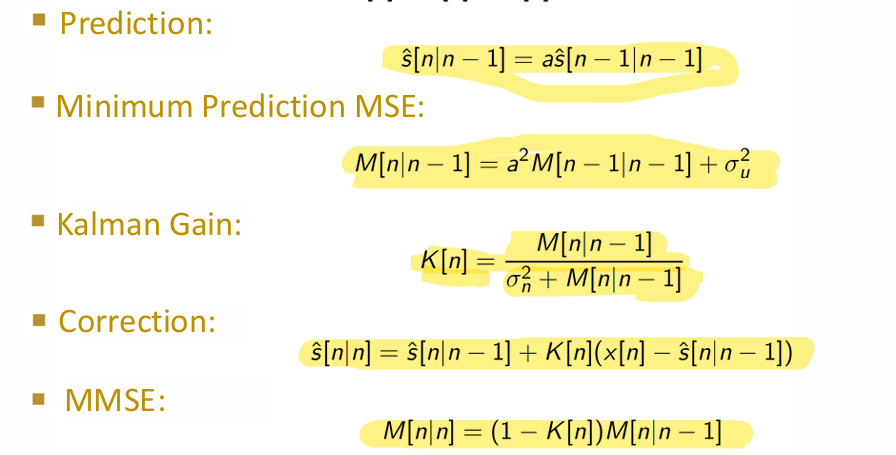

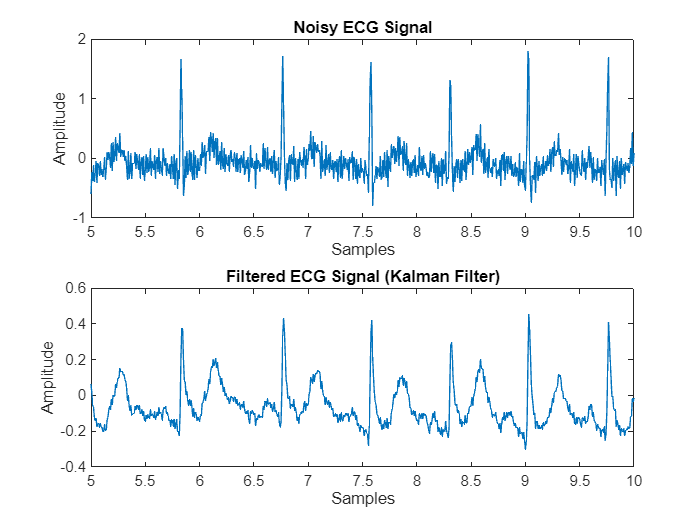

% Initialize the Kalman filter parameters
A = 1; % State transition matrix
H = 1; % Observation matrix
R = 1e-3; % Process noise covariance (adjust as needed)
Q = 0.027; % Measurement noise covariance (adjust as needed)
x_est = 0; % Initial state estimate
P = 1; % Initial estimate covariance

% Create a vector to store the filtered signal
filteredECG = zeros(length(nECG), 1);

% Apply the Kalman filter
for k = 1:length(nECG)
    % Prediction step
    x_pred = A * x_est;
    P_pred = A * P * A' + R;
    
    % Update step
    K = P_pred * H' / (H * P_pred * H' + Q); % Kalman gain
    x_est = x_pred + K * (nECG(k) - H * x_pred);
    P = (1 - K * H) * P_pred;
    
    % Store the filtered estimate
    filteredECG(k) = x_est;
end

% Plot results
figure('Name','Filtered-Kalman filter');
subplot(2, 1, 1);
plot(t,nECG);
title('Noisy ECG Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([5,10]);

subplot(2, 1, 2);
plot(t,filteredECG);
title('Filtered ECG Signal (Kalman Filter)');
xlabel('Samples');
ylabel('Amplitude');
xlim([5 10]);
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Filtered_using_scalar_KF(R=1e-3).png');

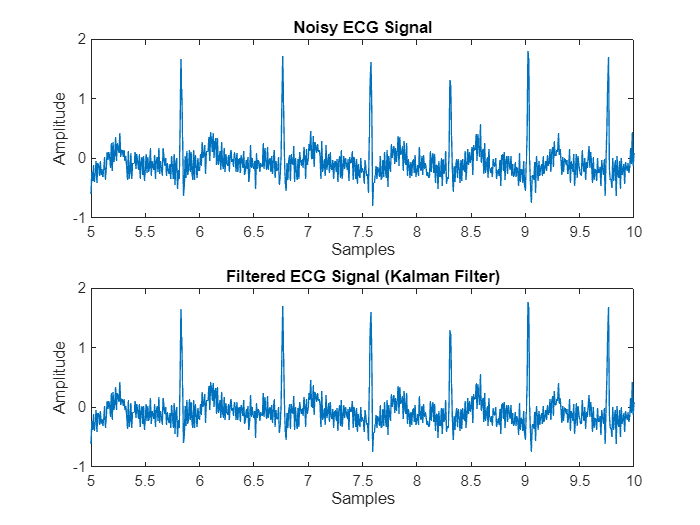

% Initialize the Kalman filter parameters
A = 1; % State transition matrix
H = 1; % Observation matrix
R = 1; % Process noise covariance (adjust as needed)
Q = 0.027; % Measurement noise covariance (adjust as needed)
x_est = 0; % Initial state estimate
P = 1; % Initial estimate covariance

% Create a vector to store the filtered signal
filteredECG = zeros(length(nECG), 1);

% Apply the Kalman filter
for k = 1:length(nECG)
    % Prediction step
    x_pred = A * x_est;
    P_pred = A * P * A' + R;
    
    % Update step
    K = P_pred * H' / (H * P_pred * H' + Q); % Kalman gain
    x_est = x_pred + K * (nECG(k) - H * x_pred);
    P = (1 - K * H) * P_pred;
    
    % Store the filtered estimate
    filteredECG(k) = x_est;
end

% Plot results
figure('Name','Filtered-Kalman filter');
subplot(2, 1, 1);
plot(t,nECG);
title('Noisy ECG Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([5,10]);

subplot(2, 1, 2);
plot(t,filteredECG);
title('Filtered ECG Signal (Kalman Filter)');
xlabel('Samples');
ylabel('Amplitude');
xlim([5 10]);
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Filtered_using_scalar_KF(R=1).png');

% Initialize the Kalman filter parameters
A = 1; % State transition matrix
H = 1; % Observation matrix
R = 1e-6; % Process noise covariance (adjust as needed)
Q = 0.027; % Measurement noise covariance (adjust as needed)
x_est = 0; % Initial state estimate
P = 1; % Initial estimate covariance

R_array = linspace(1e-3,1,1000);
MSE = zeros(size(R_array));

for i = (1:length(R_array))
% Create a vector to store the filtered signal
filteredECG = zeros(length(nECG), 1);

% Apply the Kalman filter
for k = 1:length(nECG)
    % Prediction step
    x_pred = A * x_est;
    P_pred = A * P * A' + R_array(i);
    
    % Update step
    K = P_pred * H' / (H * P_pred * H' + Q); % Kalman gain
    x_est = x_pred + K * (nECG(k) - H * x_pred);
    P = (1 - K * H) * P_pred;
    
    % Store the filtered estimate
    filteredECG(k) = x_est;
end
MSE(i) = mean((filteredECG'-idealECG).^2);
end

[M, I] = min(MSE)

M = 0.0149

I = 44

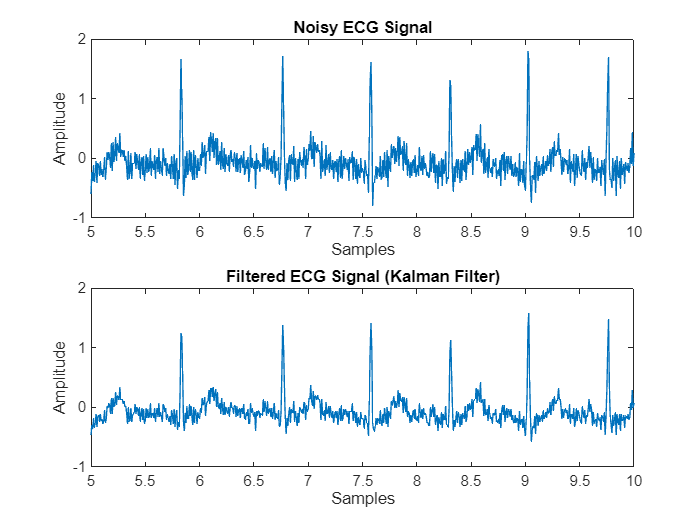

% Initialize the Kalman filter parameters
A = 1; % State transition matrix
H = 1; % Observation matrix
R = R_array(I); % Process noise covariance (adjust as needed)
Q = 0.027; % Measurement noise covariance (adjust as needed)
x_est = 0; % Initial state estimate
P = 1; % Initial estimate covariance

% Create a vector to store the filtered signal
filteredECG = zeros(length(nECG), 1);

% Apply the Kalman filter
for k = 1:length(nECG)
    % Prediction step
    x_pred = A * x_est;
    P_pred = A * P * A' + R;
    
    % Update step
    K = P_pred * H' / (H * P_pred * H' + Q); % Kalman gain
    x_est = x_pred + K * (nECG(k) - H * x_pred);
    P = (1 - K * H) * P_pred;
    
    % Store the filtered estimate
    filteredECG(k) = x_est;
end

% Plot results
figure('Name','Filtered-Kalman filter');
subplot(2, 1, 1);
plot(t,nECG);
title('Noisy ECG Signal');
xlabel('Samples');
ylabel('Amplitude');
xlim([5,10]);

subplot(2, 1, 2);
plot(t,filteredECG);
title('Filtered ECG Signal (Kalman Filter)');
xlabel('Samples');
ylabel('Amplitude');
xlim([5 10]);

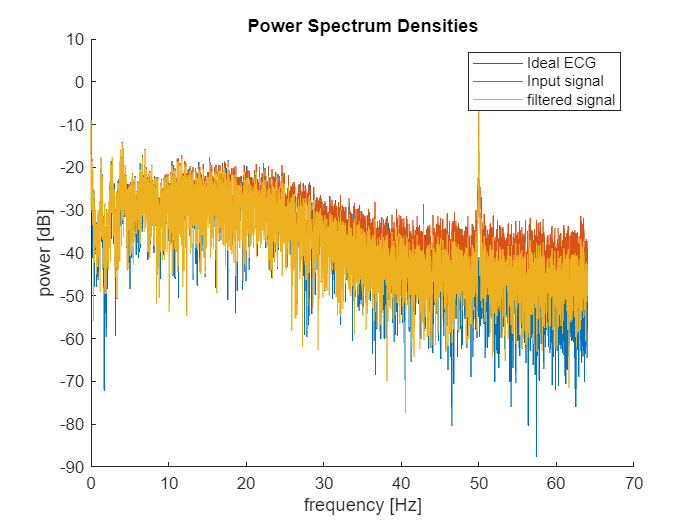

% saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\Filtered_using_scalar_KF(R_opt).png');
% PSD analysis 
[p_ideal, f] = periodogram(idealECG, [], [], fs);
[p_x, ~] = periodogram(nECG, [], [], fs);
[p_filtered, ~] = periodogram(filteredECG, [], [], fs);

figure(6);
clf;
hold on;
plot(f,10*log10(p_ideal));
plot(f,10*log10(p_x));
plot(f,10*log10(p_filtered));
hold off;
xlabel('frequency [Hz]');
ylabel('power [dB]');
title('Power Spectrum Densities')
legend ('Ideal ECG','Input signal','filtered signal');
saveas(gcf, 'D:\UoM\Autonomous systems\Mini_project\Report\Images\PSD_scalar_KF.png');